# **Vision Artificial. GIEC.**

# **Sistemas de Vision Artificial. GIC.**

**Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 6: exercise 02 - Corrección de la Perspectiva con Homografía

Para corregir la perspectiva de un objeto es necesario estimar la transformación de la perspectiva. Cuatro pares de puntos correspondientes son suficientes para recuperar una transformación de perspectiva entre dos imágenes. El objetivo de esta práctica es correjir la perspectiva de la carta de la imagen "`card.jpg`".

clc;
clear all;
close all;

Step 1) Load image.

% Read original image.
I = imread('card.jpg');

Step 2) Click on the four corners.

% NOTE: impixel 
% Use normal button clicks to select pixels. 
% Press Backspace or Delete to remove the previously selected pixel. 
% To add a final pixel and finish pixel selection in one step, press shift-click, or right-click or double-click. 
% To finish selecting pixels without adding a final pixel, press Return.
[x, y , P] = impixel(I);
srcPoints = [x y];

Step 3) Projected four points

scale = 2; % px/mm
card_w = 67 * scale;
card_h = 100 * scale;
dstPoints = [];

Step 4) Estimate the perspective transformation (Homography)    `estimateGeometricTransform`

Step 5) Apply the perspective transformation    `imwarp`

Se pide: 

         1. Cargue la imagen "`card.jpg`". Haga clic en las cuatro esquinas de la tarjeta para obtener los primeros cuatro puntos utilizando la función `impixel`. Nota: utilice el siguiente orden para obtener los cuatro puntos: 1) Esquina superior izquierda, 2) Esquina superior derecha, 3) Esquina inferior derecha, 4) Esquina inferior izquierda.

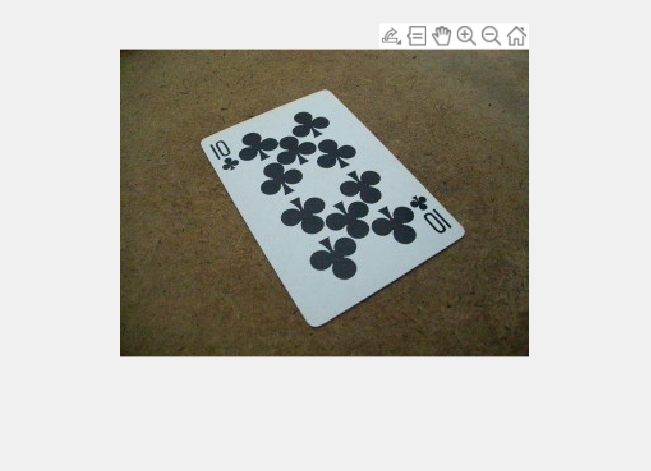

I = imread('card.jpg');
[x, y , P] = impixel(I);

srcPoints = [x y]

         2. Calcule los cuatro puntos de la carta de póquer sin distorsión de perspectiva, teniendo en cuenta que una carta de póquer tiene un tamaño de `67 mm` por `100 mm` aproximadamente.

scale = 2; % px/mm
card_w = 67 * scale;
card_h = 100 * scale;
dstPoints = [0,0; card_w, 0; card_w, card_h; 0, card_h];

         3. Estime la transformación de la perspectiva utilizando la función `estimateGeometricTransform`. (Step 4) 

tform = estimateGeometricTransform(srcPoints, dstPoints, 'projective');

         4. Aplicar la transformación de perspectiva utilizando la función `imwarp`. (Step 5) Nota: para que la imagen transformada mantenga el tamaño de la imagen original debe indicarse en a función imwarp la opción` 'OutputView',outputView,` donde **outputView** se clacula con la función `outputView = imref2d(size(I));`

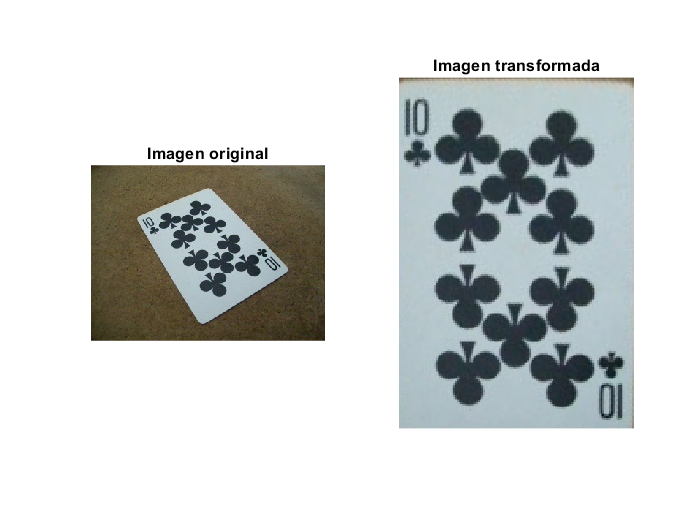

outputView = imref2d([card_h card_w 3]);
I_warp = imwarp(I, tform, 'OutputView', outputView);

figure;
subplot(1,2,1); imshow(I);      title('Imagen original');
subplot(1,2,2); imshow(I_warp); title('Imagen transformada');

**Hemos decidido recortar solo la carta, pasando a la variable *****outputView***** el tamaño de la carta en píxeles **`[card_h card_w 3]`**, en lugar de pasar el tamaño de la imagen I.**

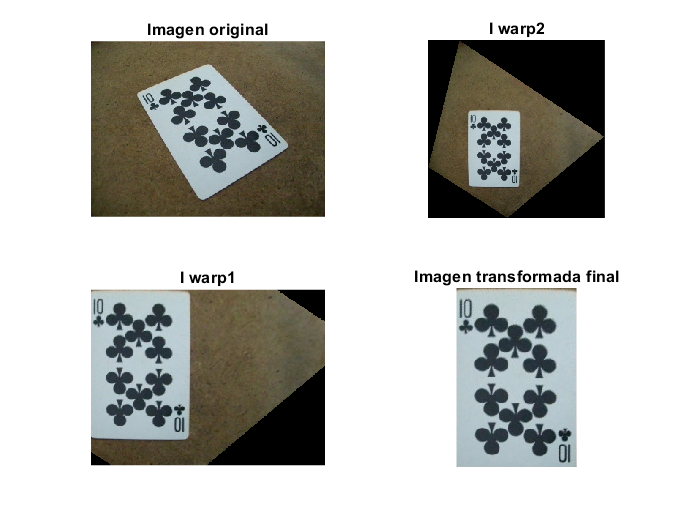

outputView1 = imref2d([size(I)]);
I_warp1 = imwarp(I, tform, 'OutputView', outputView1);
I_warp2 = imwarp(I, tform);

figure;
subplot(2,2,1); imshow(I);       title('Imagen original');
subplot(2,2,2); imshow(I_warp2); title('I warp2');
subplot(2,2,3); imshow(I_warp1); title('I warp1');
subplot(2,2,4); imshow(I_warp);  title('Imagen transformada final');